clear

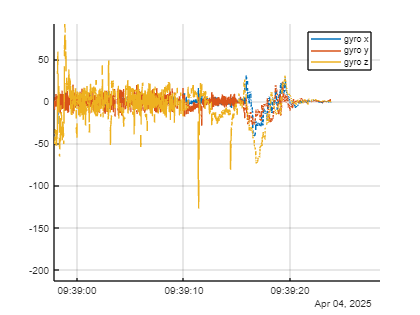

% Read the CSV log file (automatically skips the header row)
data = readmatrix('logfile.csv');

% Assign each column to a named variable
time      = data(:, 1);
timestamp = datetime(time, 'ConvertFrom', 'posixtime');
state     = data(:, 2);
x         = data(:, 3);
y         = data(:, 4);
h         = data(:, 5);
frame_id  = data(:, 6);
line_pos  = data(:, 7);
eKp       = data(:, 8);
turn_rate = data(:, 9);
valid_cnt = data(:, 10);
tripA     = data(:, 11);
tripAh    = data(:, 12);
tripB     = data(:, 13);
tripBh    = data(:, 14);
ir_L      = data(:, 15);
ir_R      = data(:, 16);
acc_x     = data(:, 17);
acc_y     = data(:, 18);
acc_z     = data(:, 19);
gyro_x    = data(:, 20);
gyro_y    = data(:, 21);
gyro_z    = data(:, 22);

figure
hold on
plot(timestamp, gyro_x)
plot(timestamp, gyro_y)
plot(timestamp, gyro_z)
legend("gyro x", "gyro y", "gyro z")
grid
hold off

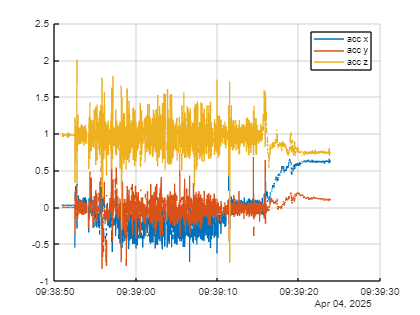

figure
hold on
plot(timestamp, acc_x)
plot(timestamp, acc_y)
plot(timestamp, acc_z)
legend("acc x", "acc y", "acc z")
grid
hold off

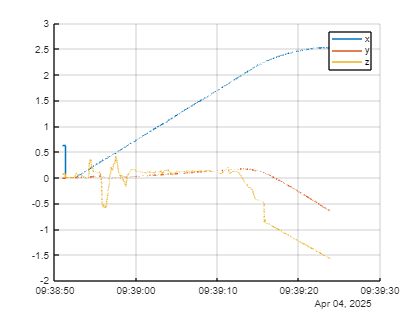


figure
hold on
plot(timestamp, x)
plot(timestamp, y)
plot(timestamp, h)
legend("x", "y", "z")
grid
hold off

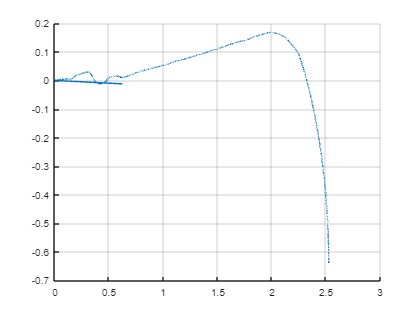

figure
hold on
plot(x, y)
grid
hold off